# **ETSMP - CONTINUOUS RANDOM VARIABLES**

***MADS STEINER KRISTENSEN***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

# **INITIALIZATION**

clc
clear

# **PROBLEM 2.18**

**Show that the expected value operator has the following properties.**

**A:** $E\left\lbrack a+\mathrm{bX}\right\rbrack =a+b\left\lbrack X\right\rbrack$

**B:** $E\left\lbrack \mathrm{aX}+\mathrm{bY}\right\rbrack =a\cdot E\left\lbrack X\right\rbrack +b\cdot E\left\lbrack Y\right\rbrack$

**C:** $\mathrm{var}\left(\mathrm{aX}+\mathrm{bY}\right)=a^2 \cdot \mathrm{var}\left(X\right)+b^2 \cdot \mathrm{var}\left(Y\right)+2\mathrm{ab}\cdot \mathrm{covar}\left(X,Y\right)$

## [A] ESTIMATED VALUE

#### 
$$E\left\lbrack a+b\cdot \;X\right\rbrack =\int a\cdot f_{X\left(x\right)} \;\mathrm{dx}+\int b\cdot x\cdot f_{X\left(x\right)} \;\mathrm{dx}$$


#### 
$$E\left\lbrack a+b\cdot X\right\rbrack =a\cdot \int f_{X\left(x\right)} \;\mathrm{dx}+b\cdot \int x\cdot f_{X\left(x\right)} \;\mathrm{dx}$$


#### 
$$E\left\lbrack a+b\cdot X\right\rbrack =a+b\cdot E\left\lbrack X\right\rbrack$$


## [B] ESTIMATED VALUE

#### 
$$E\left\lbrack a\cdot X+b\cdot Y\right\rbrack =\int a\cdot \;x\cdot f_{X\left(x\right)} \mathrm{dx}+\int b\cdot y\cdot f_{Y\left(y\right)} \;\mathrm{dx}$$


#### 
$$E\left\lbrack a\cdot X+b\cdot Y\right\rbrack =a\cdot \int x\cdot f_{X\left(x\right)} \;\mathrm{dx}+b\cdot \int y\cdot f_{Y\left(y\right)} \;\mathrm{dy}$$


#### 
$$E\left\lbrack a\cdot X+b\cdot Y\right\rbrack =a\cdot E\left\lbrack X\right\rbrack +b\cdot E\left\lbrack Y\right\rbrack$$


## [C] VARIANCE

#### 
$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =E\left\lbrack {\left(aX+bY\right)}^2 \right\rbrack -E{\left\lbrack aX+bY\right\rbrack }^2$$


#### 
$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =\int {\left(ax+by\right)}^2 \cdot f_{X,Y\left(x,y\right)} \;dx\;dy-{\left(a\cdot E\left\lbrack X\right\rbrack +b\cdot E\left\lbrack Y\right\rbrack \right)}^2$$


#### 
$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =\int \left(a^2 x^2 +b^2 y^2 +2axby\right)\cdot f_{X,Y} \left(x,y\right)\;dx\;dy-{\left(a\cdot E\left\lbrack X\right\rbrack +b\cdot E\left\lbrack Y\right\rbrack \right)}^2$$


#### 
$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =a^2 \cdot \int x^2 \cdot f_{X\left(x\right)} \;dx-a^2 \cdot E{\left\lbrack X\right\rbrack }^2 +b^2 \cdot \int y^2 \cdot f_{Y\left(y\right)} \;\mathrm{dy}-b^2 \cdot E{\left\lbrack Y\right\rbrack }^2 +2ab\cdot \int xy\cdot f_{X,Y\left(x,y\right)} \;dx\;dy-2ab\cdot E\left\lbrack X\right\rbrack \cdot E\left\lbrack Y\right\rbrack$$


#### 
$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =a^2 \cdot \left(E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 \right)+b^2 \cdot \left(E\left\lbrack Y^2 \right\rbrack -E{\left\lbrack Y\right\rbrack }^2 \right)+2ab\cdot \mathrm{COVAR}\left\lbrack X,Y\right\rbrack$$


#### 
$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =a^2 \cdot \mathrm{VAR}\left\lbrack X\right\rbrack +b^2 \cdot \mathrm{VAR}\left\lbrack Y\right\rbrack +2ab\cdot \mathrm{COVAR}\left\lbrack X,Y\right\rbrack$$


# **PROBLEM 2.24**

**X is a Gaussian random variable with **$\mu_x =2$ **and **$\sigma_x^2 =9$. **Find **$P\left(-4<X\le 5\right)$**using tabulated values of **$Q\left(\ldotp \right)$ 

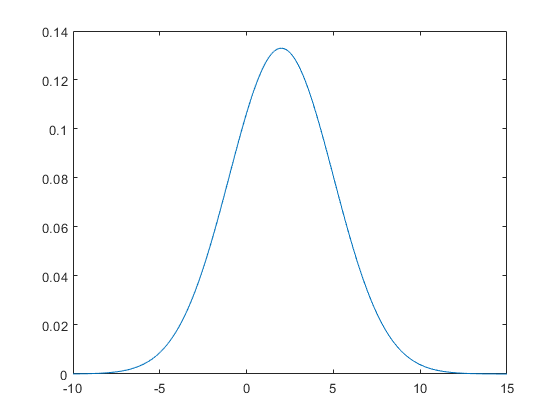

mu = 2;
sigmasquared = 9;
sigma = sqrt(sigmasquared);

LProbability = normcdf(-4, mu, sigma);
HProbability = normcdf(5, mu, sigma);

Probability = HProbability - LProbability;

x = -10:.1:15;
y = normpdf(x, mu, sigma);
plot(x, y)

# **PROBLEM 2.29**

**Show that the expected value operator has the following properties.**